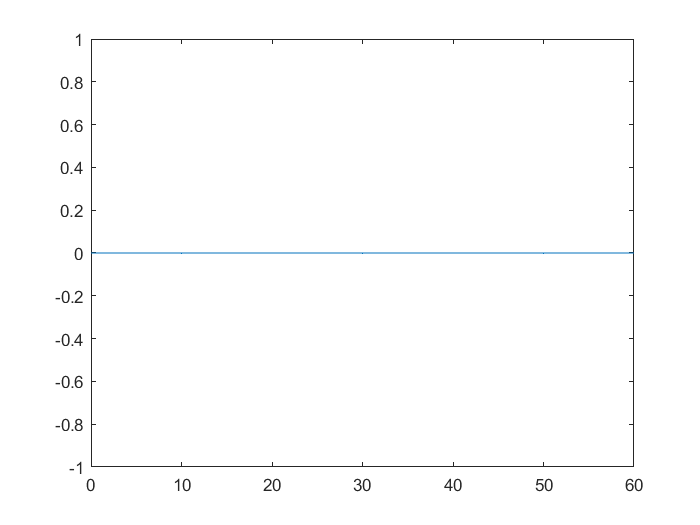

% NO FEEDBACK MODELS
clear all; clc; close all;

% PARAMETERS
x_initials = [0, 9*10^-13, 0, 0, 0, 10^-13, 0, 0, 10^-12, 0, 10^-13, 0, 0.31, 99.4, 0.29, 100, 0, 100, 0, 96, 4];
tspan = linspace(0,60,31);
options = odeset('RelTol',1e-12,'AbsTol',1e-12);

% SOLVE ODE
[t, x] = ode45(@InsulinModel, tspan, x_initials, options);

% FIGURE FORMAT
figure();
marker_size = 15;
label_fs    = 10;
lgd_fs      = 6;
xrange      = [-5,65];
a           = [0, 0.4470, 0.7410];
b           = [0.6350, 0.0780, 0.1840];

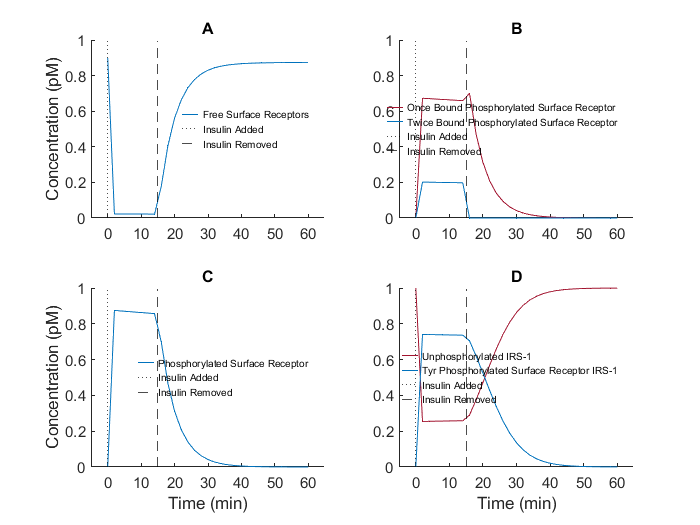


% FIGURE 6A
subplot(2,2,1)
hold on
plot(t, x(:,2) * 10^12, 'Color', a)
xline(0, ':k'); xline(15, '--k');
hold off

title("A"); 
ylabel("Concentration (pM)", 'FontSize', label_fs)
set(gca, 'box', 'off'); set(gca,'TickLength',[0.02, 0.2]); set(gca,'Xtick',0:10:60); set(gca,'Ytick',0:0.2:1);
xlim(xrange); ylim([0,1]);
L = legend("Free Surface Receptors","Insulin Added","Insulin Removed", 'FontSize', lgd_fs, "Location", "east"); L.ItemTokenSize(1) = 10; legend boxoff;

% FIGURE 6B
subplot(2,2,2)
hold on
plot(t, x(:,5) * 10^12, 'Color', b); plot(t, x(:,4) * 10^12, 'Color', a);
xline(0, ':k'); xline(15, '--k');
hold off

title("B")
set(gca, 'box', 'off'); set(gca,'TickLength',[0.02, 0.2]);
set(gca,'Xtick',0:10:60); set(gca,'Ytick',0:0.2:1);
xlim(xrange); ylim([0,1]);
L = legend("Once Bound Phosphorylated Surface Receptor", "Twice Bound Phosphorylated Surface Receptor", "Insulin Added","Insulin Removed",'FontSize', lgd_fs, "Location", "east"); L.ItemTokenSize(1) = 10; legend boxoff;

% FIGURE 6C
subplot(2,2,3)
hold on
plot(t, (x(:,4) + x(:,5)) * 10^12, 'Color', a)
xline(0, ':k'); xline(15, '--k');
hold off

title("C")
xlabel("Time (min)", 'FontSize', label_fs); ylabel("Concentration (pM)", 'FontSize', label_fs)
set(gca, 'box', 'off'); set(gca,'TickLength',[0.02, 0.2]);
set(gca,'Xtick',0:10:60); set(gca,'Ytick',0:0.2:1);
xlim(xrange); ylim([0,1]);
L = legend("Phosphorylated Surface Receptor","Insulin Added","Insulin Removed", 'FontSize', lgd_fs, "Location", "east", 'color','none'); L.ItemTokenSize(1) = 10; legend boxoff;

% FIGURE 6D
subplot(2,2,4)
hold on
plot(t, x(:,9) * 10^12, 'Color', b)
plot(t, x(:,10) * 10^12, 'Color', a)
xline(0, ':k'); xline(15, '--k')
hold off
title("D")
xlabel("Time (min)", 'FontSize', label_fs)
set(gca, 'box', 'off')
set(gca,'Xtick',0:10:60)
set(gca,'Ytick',0:0.2:1)
set(gca,'TickLength',[0.02, 0.2])
xlim(xrange)
ylim([0,1])
L = legend("Unphosphorylated IRS-1", "Tyr Phosphorylated Surface Receptor IRS-1","Insulin Added","Insulin Removed",'FontSize', lgd_fs, "Location", "east");
L.ItemTokenSize(1) = 10;
legend boxoff  

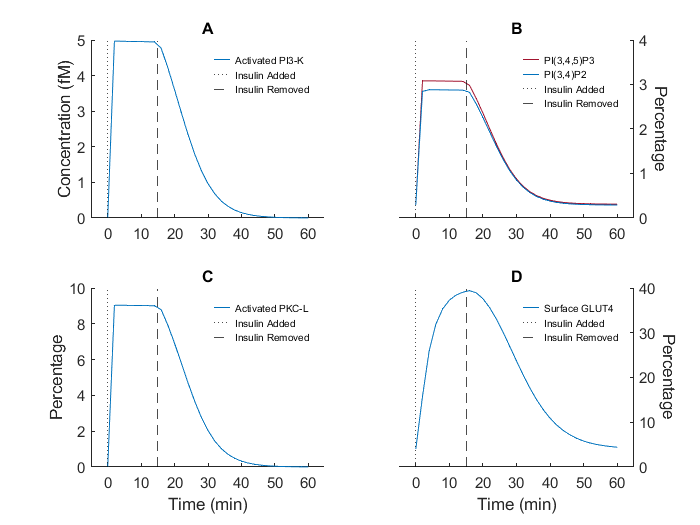


% FIGURE 7A
figure();
subplot(2,2,1)
hold on
plot(t, x(:,12) * 10 ^ 15, 'Color', a)
xline(0, ':k'); xline(15, '--k')
hold off
title("A")
ylabel("Concentration (fM)", 'FontSize', label_fs)
set(gca, 'box', 'off')
set(gca,'Xtick',0:10:60)
set(gca,'Ytick',0:1:5)
set(gca,'TickLength',[0.02, 0.2])
xlim(xrange)
ylim([0,5])
L = legend("Activated PI3-K","Insulin Added","Insulin Removed", 'FontSize', lgd_fs, "Location", "northeast");
L.ItemTokenSize(1) = 10;
legend boxoff  

% FIGURE 7B
subplot(2,2,2)
hold on
plot(t, x(:,13), 'Color', b)
plot(t, x(:,15), 'Color', a)
xline(0, ':k'); xline(15, '--k')
hold off
title("B")
ylabel("Percentage", 'FontSize', label_fs, 'Rotation',-90,'VerticalAlignment','bottom', 'HorizontalAlignment','center')
set(gca, 'box', 'off')
set(gca,'Xtick',0:10:60)
set(gca,'Ytick',0:1:4)
set(gca,'TickLength',[0.02, 0.2])
set(gca,'YAxisLocation','right')
xlim(xrange)
ylim([0,4])
L = legend("PI(3,4,5)P3", "PI(3,4)P2", "Insulin Added","Insulin Removed",'FontSize', lgd_fs, "Location", "northeast");
L.ItemTokenSize(1) = 10;
legend boxoff  

% FIGURE 7C
subplot(2,2,3)
hold on
plot(t, x(:,19), 'Color', a)
xline(0, ':k'); xline(15, '--k')
hold off
title("C")
xlabel("Time (min)", 'FontSize', label_fs)
ylabel("Percentage", 'FontSize', label_fs)
set(gca, 'box', 'off')
set(gca,'Xtick',0:10:60)
set(gca,'Ytick',0:2:10)
set(gca,'TickLength',[0.02, 0.2])
xlim(xrange)
ylim([0,10])
L = legend("Activated PKC-L", "Insulin Added","Insulin Removed",'FontSize', lgd_fs, "Location", "northeast", 'color','none');
L.ItemTokenSize(1) = 10;
legend boxoff  

% FIGURE 7D
subplot(2,2,4)
hold on
plot(t, x(:,21), 'Color', a)
xline(0, ':k'); xline(15, '--k')
hold off
title("D")
xlabel("Time (min)", 'FontSize', label_fs)
ylabel("Percentage", 'FontSize', label_fs, 'Rotation',-90,'VerticalAlignment','bottom', 'HorizontalAlignment','center')
set(gca, 'box', 'off')
set(gca,'Xtick',0:10:60)
set(gca,'Ytick',0:10:40)
set(gca,'TickLength',[0.02, 0.2])
set(gca,'YAxisLocation','right')
xlim(xrange)
ylim([0,40])
L = legend("Surface GLUT4", "Insulin Added","Insulin Removed",'FontSize', lgd_fs, "Location", "northeast");
L.ItemTokenSize(1) = 10;
legend boxoff 

function dxdt = InsulinModel(t,x)

% PARAMETERS
IRp  = 8.97 * 10^-13;
SHIP = 1;
PTEN = 1;
PTP  = 1; 
APeq = 100/11;
PI3K = 5 * 10^-15;
effect = (0.2.*x(17) + 0.8.*x(19)) ./ APeq;

% RATE CONSTANTS
k1      = 6 * 10^7;
k_1     = 0.20;
k2      = k1;
k_2     = 100 * k_1;
k3      = 2500;
k_3     = k_1;
k_4     = 0.003;
k4      = k_4/9;  
k4_     = 2.1 * 10^-3; 
k_4_    = 2.1 * 10^-4;
k_5     = 1.67 * 10^-18;
k5      = get_k5(x(6), x(7), x(8), k_5);
k6      = 0.461;     
k7      = 4.16;
k_7     = (2.5/7.45) * k7;
k_8     = 10;
k8      = k_8 * (5/70.775) * 10^12;    
k9_sim  = 1.39;
k_9     = (94/3.1) * k9_sim;
k9_bas  = (0.31/99.4) * k_9;
k9      = (k9_sim - k9_bas) .* (x(12) ./ PI3K) + k9_bas;  
k_10    = 2.77;
k10     = (3.1/2.9) * k_10;  
k_11    = 10 * log(2);
k11     = 0.1 .* k_11 .* (x(13) - 0.31) ./ (3.10-0.31); 
k_12    = 10 * log(2);
k12     = 0.1 .* k_12 .* (x(13) - 0.31) ./ (3.10-0.31); 
k_13    = 0.167;
k13     = (4/96) * k_13;   
k13_    = (40/60 - 4/96) .* k_13 .* effect;
k_14    = 0.001155;
k14     = 96 * k_14; 

% INSULIN INPUT
if t < 15 %21
    x(1,:) = 10^-7; %- 0.5 * 10^-7 * cos(0.3 * t) + 0.5 * 10^-7;
else 
    x(1,:) = 0;
end

% DIFFERENTIAL EQUATIONS
dxdt = [];
dxdt(1,:)  = 0;
dxdt(2,:)  = k_1.*x(3) + k_3.*PTP.*x(5) - k1.*x(1).*x(2) + k_4.*x(6) - k4.*x(2);
dxdt(3,:)  = k1.*x(1).*x(2) - k_1.*x(3) - k3.*x(3);
dxdt(4,:)  = k2.*x(1).*x(5) - k_2.*x(4) + k_4_.*x(7) - k4_.*x(4);
dxdt(5,:)  = k3.*x(3) + k_2.*x(4) - k2.*x(1).*x(5) - k_3.*PTP.*x(5) + k_4_.*x(8) - k4_.*x(5);
dxdt(6,:)  = k5 - k_5.*x(6) + k6.*PTP.*(x(7) + x(8)) + k4.*x(2) - k_4*x(6);
dxdt(7,:)  = k4_.*x(4) - k_4_.*x(7) - k6.*PTP.*x(7);
dxdt(8,:)  = k4_.*x(5) - k_4_.*x(8) - k6.*PTP.*x(8);
dxdt(9,:)  = k_7.*PTP.*x(10) - k7.*x(9).*(x(4) + x(5))./IRp;
dxdt(10,:) = k7.*x(9).*(x(4) + x(5))./IRp + k_8.*x(12) - (k_7.*PTP + k8.*x(11)).*x(10);
dxdt(11,:) = k_8.*x(12) - k8.*x(10).*x(11);
dxdt(12,:) = k8.*x(10).*x(11) - k_8.*x(12);
dxdt(13,:) = k9.*x(14) + k10.*x(15) - (k_9.*PTEN + k_10.*SHIP).*x(13);
dxdt(14,:) = k_9.*PTEN.*x(13) - k9.*x(14);
dxdt(15,:) = k_10.*SHIP.*x(13) - k10.*x(15);
dxdt(16,:) = k_11.*x(17) - k11.*x(16);
dxdt(17,:) = k11.*x(16) - k_11.*x(17);
dxdt(18,:) = k_12.*x(19) - k12.*x(18);
dxdt(19,:) = k12.*x(18) - k_12.*x(19);
dxdt(20,:) = k_13.*x(21) - (k13 + k13_).*x(20) + k14 - k_14.*x(20);
dxdt(21,:) = (k13 + k13_).*x(20) - k_13.*x(21);

end

% RATE CONSTANT FUNCTION
function k5 = get_k5(a,b,c,k_5)
    if (a + b + c) > 10^-13
        k5  = 10 * k_5;
    else 
        k5  = 60 * k_5;
    end
end